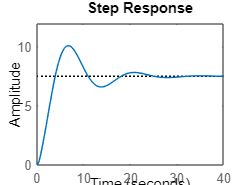

G = zpk([],[-1,-1],1);
PID = pid(2,3.5,1.5,0.5);
Sensor = tf(2,[4 5]);
r = 1;
A = tf(2, [2 6]);
F = tf(2,[3 4]); %ADICIONAMENTO DE MAIS UM SENSOR NA SAÍDA

open_loop = Sensor*G*PID*A;

T = feedback(r*G*PID,Sensor*A);
y = T;
step(y)

O cara no exemplo fazi bagulho mó complexo, mas o matlab facilita 